ON_dur = 10;
OFF_dur = 3; 
fs = 10000;
idx = 1;
start = fs*OFF_dur; stop = (ON_dur+OFF_dur)*fs;
time = T_sqr.time(idx);
% t = time{1,1}(1:T_sqr.single_trial_length(5));
period = (round(T_sqr.stim_period(idx),4))*fs;
t = 0:period;
% trial_num = 1;

stim = T_sqr.antennal_movement{idx}(:, start:stop);
% stim(4:5,:) = [];
resp = T_sqr.gcfr{idx}(:, start:stop);
% resp(4:5,:) = [];

stim = stim - mean(stim,2);
% amp = max()

 mean_pos = mean(stim, 2);
    [rows, cols] = size(resp);
%     figure;

    %%

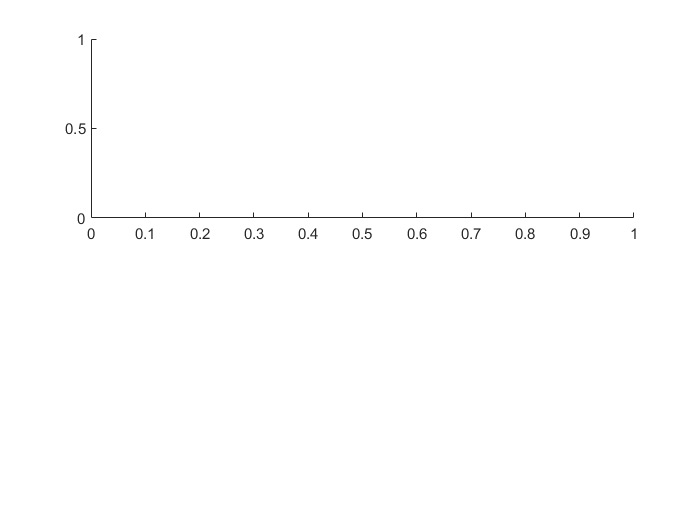

Error using fill
Vectors must be the same length.

Error in stdshade (line 41)
    fillOut = fill([F fliplr(F)],[amean+astd fliplr(amean-astd)],acolor, 'FaceAlpha', alpha,'linestyle','none');


    for i=1:rows
        locs = [];
        zc = [];
        for j = 2:cols-1
          if (stim(i,j-1)>= 0 && stim(i,j)<= 0 && stim(i,j+1)< 0)
% if (stim(i,j-1)>=mean_pos(i) && stim(i,j)<=mean_pos(i) )%&& stim(i,j+1)>mean_pos(i))
%             if (stim(i,j)<=mean_pos(i) && stim(i,j+1)>mean_pos(i))
              zc(j) = 1;
          end
        end
        
        [~,locs ]= find(zc==1);
%         figure; plot(stim(i,:)); hold on; plot(locs, stim(i,locs), 'rx');
%         figure; plot(resp(i,:)); 
        stim_clips = [];
        resp_clips = [];
        
%         figure;
        within_trial_cycle = 1;
        for k= locs(1):period:length(stim)-period
            if k+period<length(stim)
                 stim_clips(within_trial_cycle,:)  = stim(i, k:k+period);
                 resp_clips(within_trial_cycle,:) = resp(i, k:k+period);
    %              figure;
    %              subplot(2,1,1); plot(resp_clips(trial_num,:)); hold on;
    %              ylabel 'GCFR';
                     
    %              subplot(2,1,2); plot(stim_clips(trial_num,:)); hold on;
    %              ylabel 'Antennal movement'
    %              xlabel 'time (s)'
                 within_trial_cycle = within_trial_cycle +1;
            end
        end 
        f(rows) = figure;
        subplot(2,1,1); stdshade(resp_clips, 0.6, [0.4660 0.6740 0.1880], t); hold on;
         ylabel 'GCFR';
%          
        subplot(2,1,2); stdshade(stim_clips, 0.6, [0.6, 0.2,0], t); hold on;
         ylabel 'Antennal movement'
         xlabel 'time (s)'
         
         filename = sprintf('T_sqr_%0.01fs_t%d.png', T_sqr.stim_period(idx), rows);
         saveas(f(rows), filename, 'png');
    end